%% Array Properties 
%Define Array
arrayObject = rectangularArray;

arrayObject.Size = [10   2];
d = dipole;
d.Length= 1.76;
d.Width = 0.058759; %lambda/160;
d.Tilt = 90;
d.TiltAxis = [0 1 0];
%Define Array Elements
Element1 = reflector;
Element1.Exciter = dipole;
arrayObject.Element = [Element1 ];

% Design array at frequency 75000000Hz
arrayObject = design(arrayObject,75000000,Element1);
%arrayObject Properties Changed
arrayObject.RowSpacing = 1.9986;
arrayObject.ColumnSpacing = 1.9986;

%Element1 Properties Changed
arrayObject.Element(1).GroundPlaneLength = 2.3468;
arrayObject.Element(1).GroundPlaneWidth = 2.3468;
arrayObject.Element(1).Spacing = 0.88019;

% Update substrate properties 
arrayObject.Element(1).Substrate.Name = 'Air';
arrayObject.Element(1).Substrate.EpsilonR = 1;
arrayObject.Element(1).Substrate.LossTangent = 0;
arrayObject.Element(1).Substrate.Thickness = 0.880190656688;

Finite Rectangular Array Analysis

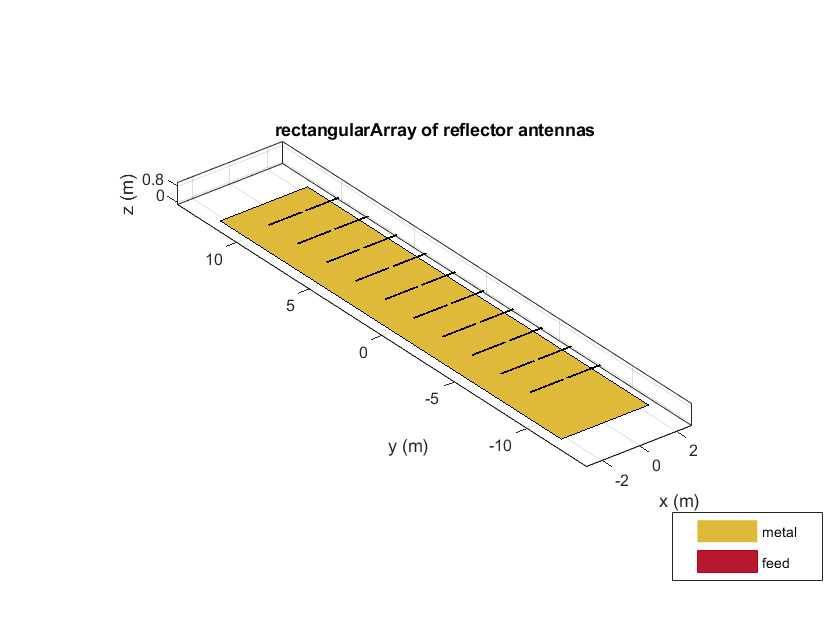

figure;
show(arrayObject) 

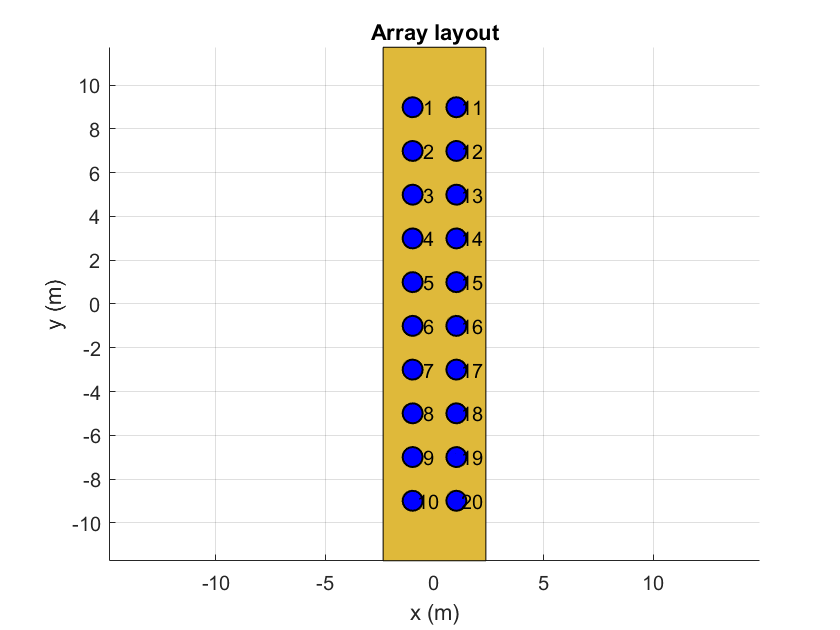

% Layout for rectangularArray
figure;
layout(arrayObject) 

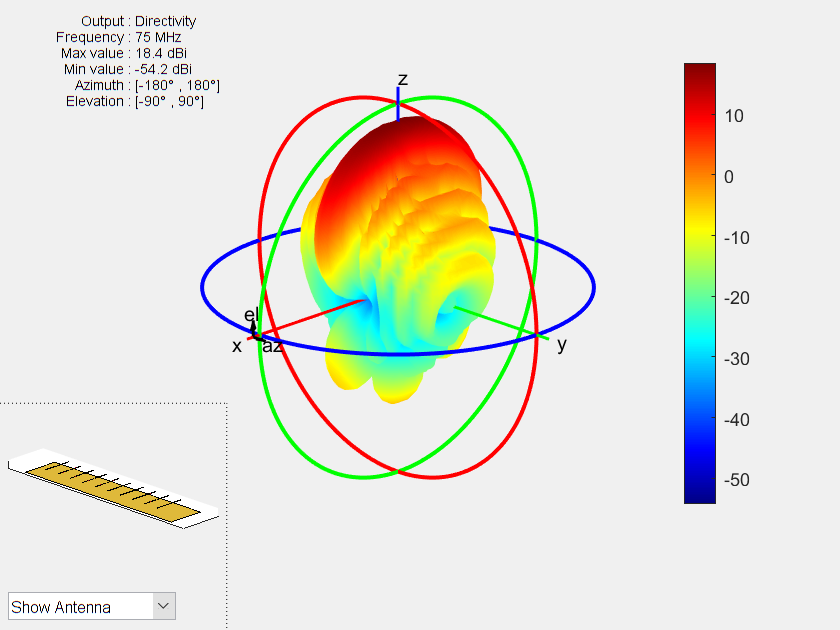

% Pattern for rectangularArray
plotFrequency = 75000000; Termination = 50;
figure;
pattern(arrayObject, plotFrequency,'Termination',Termination); 

plotFrequency = 75000000; Termination = 50;
[Directivity] = pattern(arrayObject,plotFrequency,0,90);

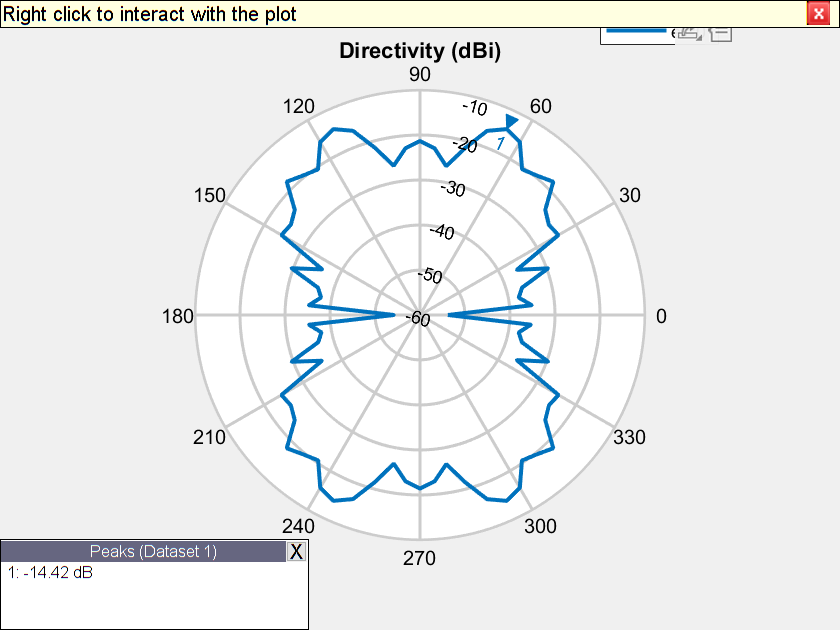

% Azimuth for rectangularArray
plotFrequency = 75000000; azRange = 0:5:360; Termination = 50;
figure;
pattern(arrayObject, plotFrequency,azRange,0,'Termination',Termination);

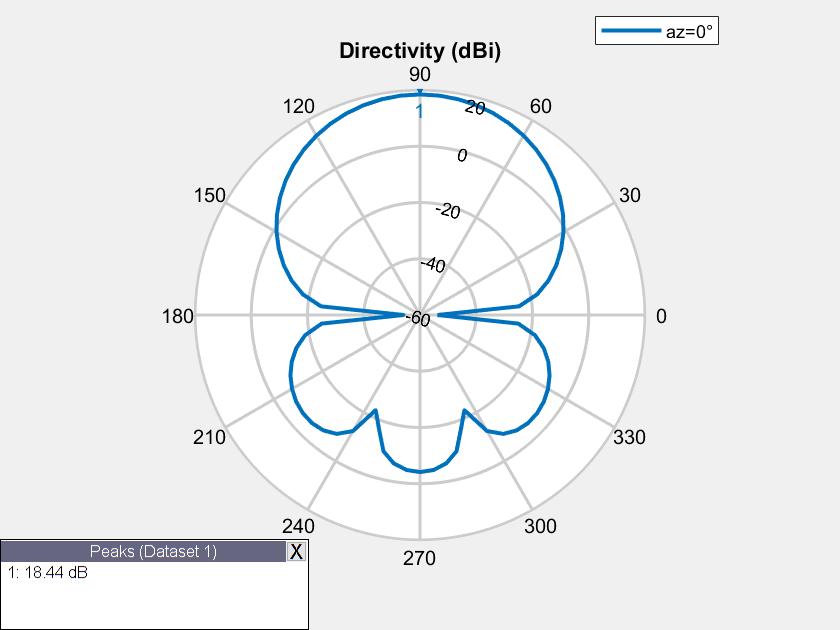

% Elevation for rectangularArray
plotFrequency = 75000000; elRange = 0:5:360; Termination = 50;
figure;
pattern(arrayObject, plotFrequency,0,elRange,'Termination',Termination);

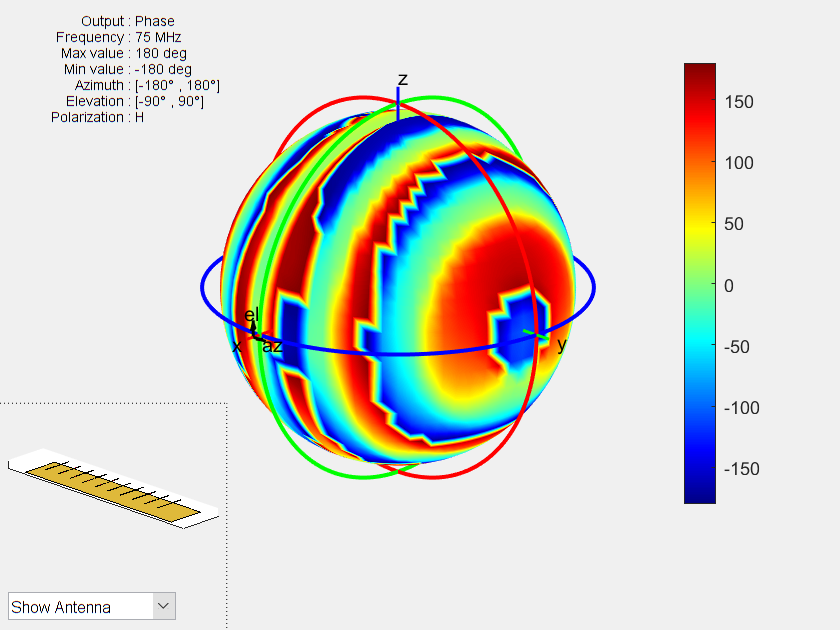

plotFrequency = 75000000; Termination = 50;
pattern(arrayObject, plotFrequency, 'Type', 'phase',"Polarization","H");

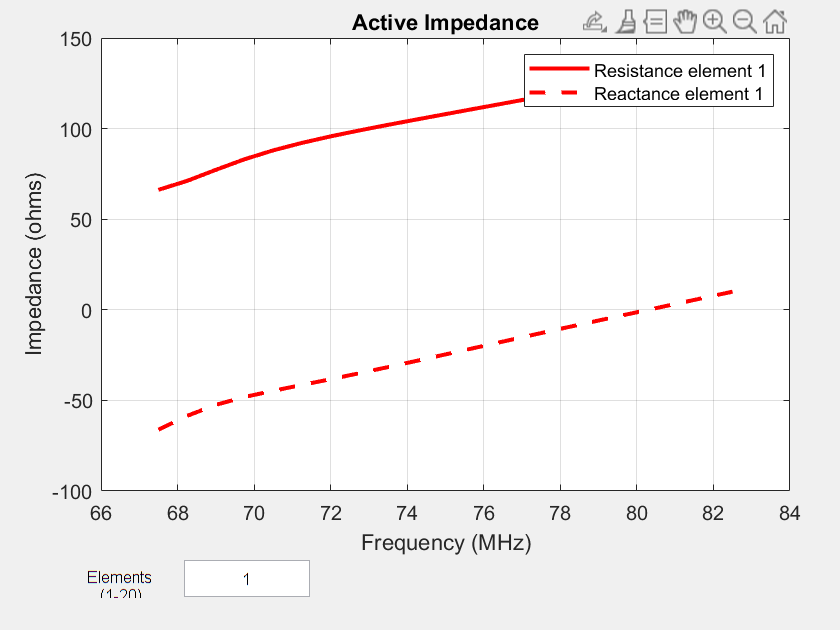

% Impedance for rectangularArray
freqRange = 67500000:750000:82500000;
figure;
impedance(arrayObject, freqRange);

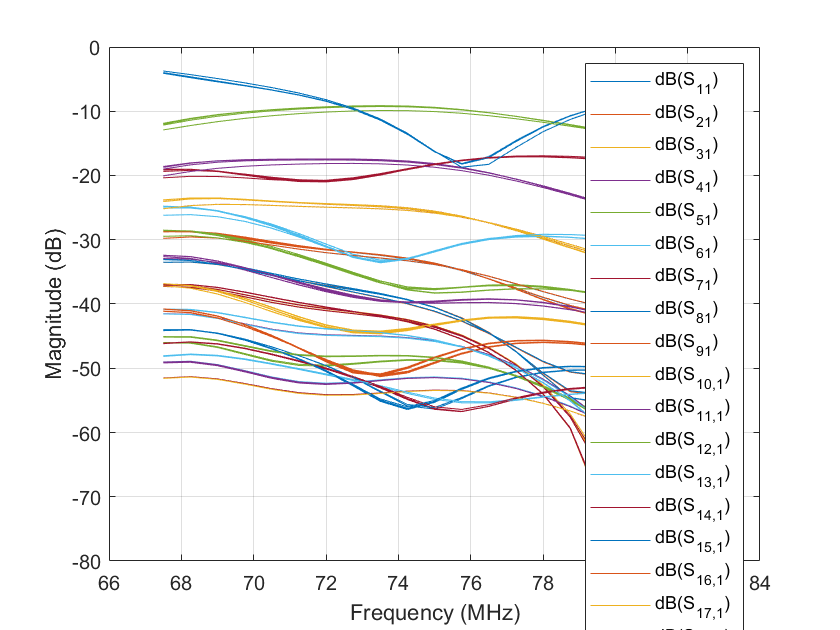

%Reflection Coefficient
% Sparameters for rectangularArray
freqRange = 67500000:750000:82500000; RefImpedance = 50;
figure;
rfplot(sparameters(arrayObject, freqRange,RefImpedance)); 

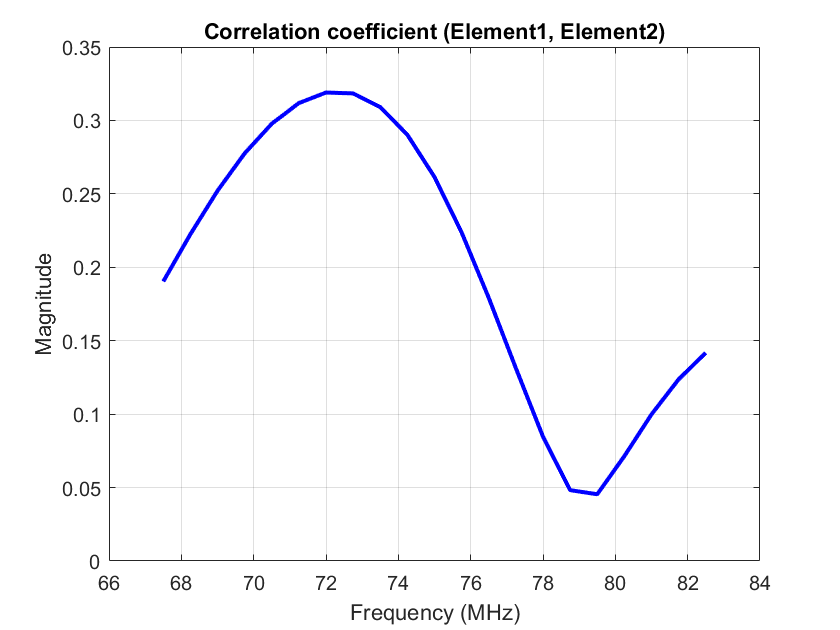

%Correlation COefficient
freqRange = 67500000:750000:82500000; RefImpedance = 50;
correlation(arrayObject,freqRange,1,2)

d = dipole;
d.Length = 1.76  %0.495*lambda;

d =   dipole with properties:

        Length: 1.7600
         Width: 0.1000
    FeedOffset: 0
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


d.Width = 0.058759 %lambda/160;

d =   dipole with properties:

        Length: 1.7600
         Width: 0.0588
    FeedOffset: 0
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


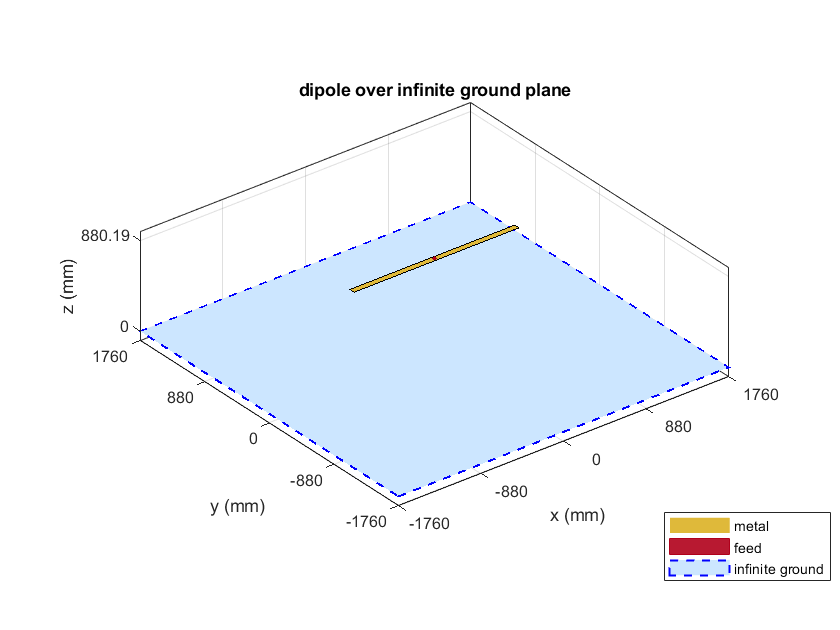

d.Tilt = 90;
d.TiltAxis = [0 1 0];

r = reflector;
r.Exciter = d;
r.Spacing = 0.88019;   %lamda/4
r.GroundPlaneLength = inf;
r.GroundPlaneWidth = inf;
figure;
show(r);

Calculate the isolated element pattern and the impedance of the above antenna. These results are used to calculate the Scan Element Pattern(SEP), also known as Array Element Pattern(AEP) or Embedded Element Pattern(EEP).

%Define az and el vectors
az = 0:2:360;
el = 90:-2:-90;
plotFrequency=75e6; Termination = 50;
% Calculate power pattern
giso = pattern(r,plotFrequency,az,el,'Type','power');  % el x az

% Calculated impedance
Ziso = impedance(r,plotFrequency);

**Calculate** **Infinite** **Array** **Scan Element Pattern**

**Unit cell**

The term *unit cell* in the infinite array analysis refers to a single element in an infinite array. A dipole backed by a reflector and a microstrip patch antenna are representative examples of a unit cell in infinite arrays. This example uses a dipole backed by a reflector and analyzes the impedance behavior at 10 GHz as a function of the scan angle. The unit cell has a cross-section of *λ*/2-by-*λ*/2.

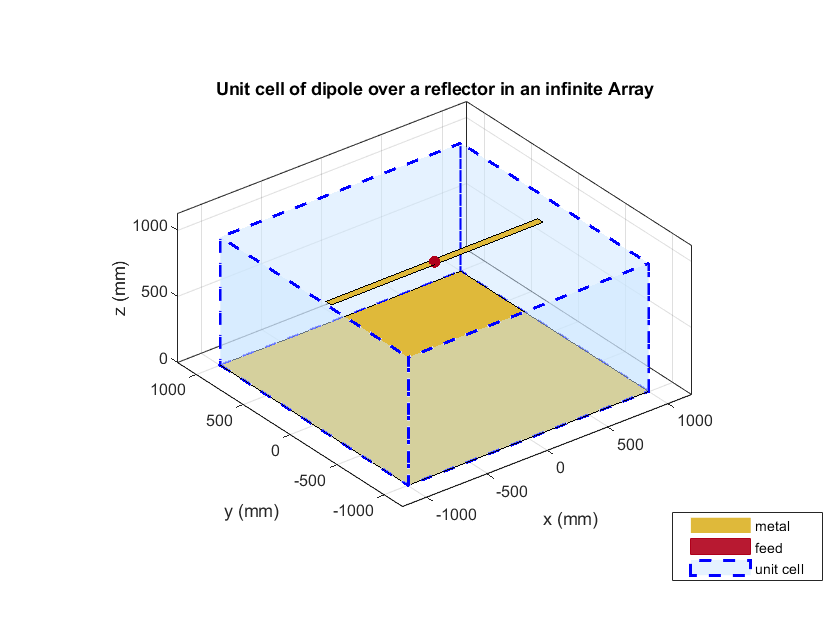

r.GroundPlaneLength = 1.9986;
r.GroundPlaneWidth = 1.9986;
infArray = infiniteArray;
infArray.Element = r;
infArray.ScanAzimuth = 30;
infArray.ScanElevation = 45;
figure;
show(infArray);

**Scan impedance**

The scan impedance at a single frequency and single scan angle is shown.

scanZ = impedance(infArray,plotFrequency)

scanZ = 64.0780 - 32.8399i

**Scan Element Pattern /****Array** **Element Pattern /Embedded Element Pattern**

The scan element pattern (SEP) is calculated from the infinite array scan impedance, the isolated element pattern and the isolated element impedance. The expression used is shown here[1],[2]:

*g**s*(*θ*)=4*R**g**R**i*(*g**i*(*θ*)) / *Z**s*(*θ*)+*Z**g*∣2

load InfArrayScanZData
scanZ = scanZ.';
Rg = 185;             
Xg = 0;
Zg = Rg + 1i*Xg;
gs = nan(numel(el),numel(az));
for i = 1:numel(el) 
    for j = 1:numel(az)
    gs(i,j) = 4*Rg*real(Ziso).*giso(i,j)./(abs(scanZ(i,j) + Zg)).^2;
    end
end

**Build Custom Antenna Element**

The scan element pattern obtained from full-wave analysis is now used in a system level analysis provided by the Phased Array System Toolbox™. For that, build a custom antenna element as a first step.

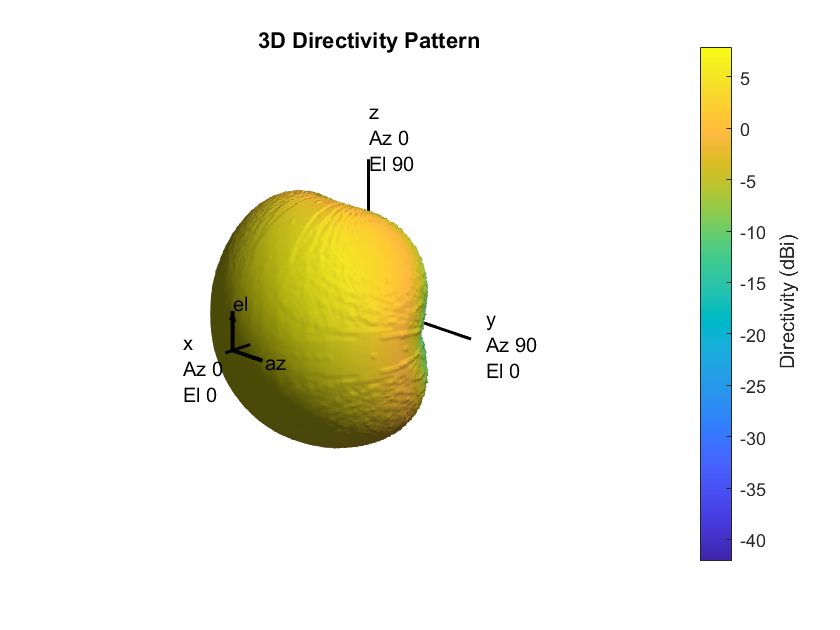

fieldpattern = sqrt(gs);
bandwidth = 3.75e6;
customAntInf = buildCustomAntenna(fieldpattern,plotFrequency,bandwidth,az,el);
figure;
pattern(customAntInf,plotFrequency);

**Build 4 -by- 4 URA**

Create a uniform rectangular array (URA) with the custom antenna element, which contains the scan element pattern. The assumption implicit in this step is that every element of this array has the same element pattern.

N = 16;
Nrow = sqrt(N);
Ncol = sqrt(N);
drow = 1.9986;
dcol = 1.9986;
myURA1 = phased.URA;
myURA1.Element = customAntInf;
myURA1.Size = [Nrow Ncol];
myURA1.ElementSpacing = [drow dcol];

**Plot Slices in E and H planes**

Calculate the pattern in the elevation plane (specified by azimuth = 0 deg and also called the E-plane) and azimuth plane (specified by elevation = 0 deg and called the H-plane) for the array built using infinite array analysis.

azang_plot = -90:0.5:90;
elang_plot = -90:0.5:90;
% E-plane
Darray1_E = pattern(myURA1,plotFrequency,0,elang_plot);
Darray1_Enormlz = Darray1_E - max(Darray1_E);
% H-plane
Darray1_H = pattern(myURA1,plotFrequency,azang_plot,0);
Darray1_Hnormlz = Darray1_H - max(Darray1_H);
% Scan element pattern in both planes
DSEP1_E = pattern(customAntInf,plotFrequency,0,elang_plot);
DSEP1_Enormlz = DSEP1_E - max(DSEP1_E);
DSEP1_H = pattern(customAntInf,plotFrequency,azang_plot,0);
DSEP1_Hnormlz = DSEP1_H - max(DSEP1_H);

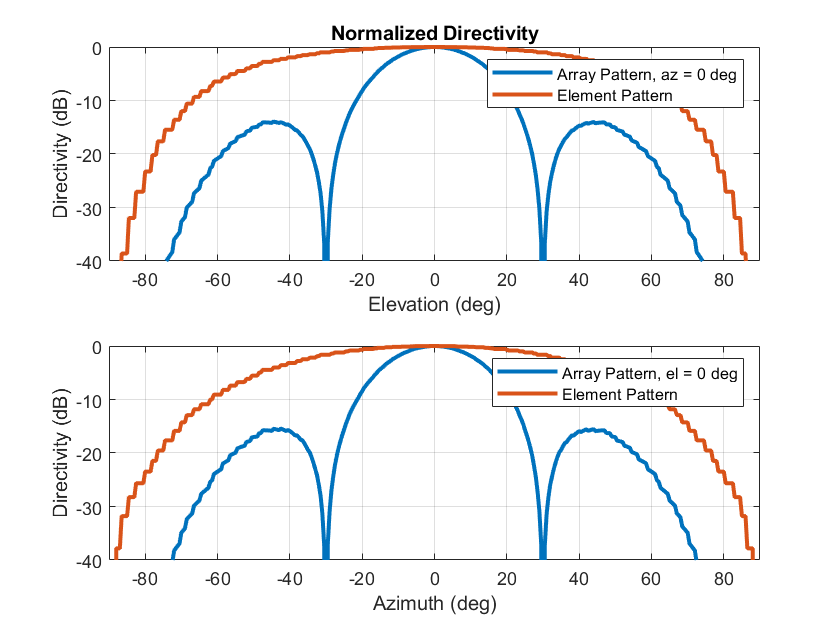

figure
subplot(211)
plot(elang_plot,Darray1_Enormlz,elang_plot,DSEP1_Enormlz,'LineWidth',2)
grid on
axis([min(azang_plot) max(azang_plot) -40 0]);
legend('Array Pattern, az = 0 deg','Element Pattern')
xlabel('Elevation (deg)')
ylabel('Directivity (dB)')
title('Normalized Directivity')
subplot(212)
plot(azang_plot,Darray1_Hnormlz,azang_plot,DSEP1_Hnormlz,'LineWidth',2)
grid on
axis([min(azang_plot) max(azang_plot) -40 0]);
legend('Array Pattern, el = 0 deg','Element Pattern')
xlabel('Azimuth (deg)')
ylabel('Directivity (dB)')

**Comparison with Full Wave Finite** **Array** **Analysis**

To understand the effect of the finite size of the array, we execute a full wave analysis of a 4 X 4 dipole array backed by an infinite reflector. The full wave array pattern slices in the E and H planes as well as the center element embedded element pattern is also calculated. 

**Load full wave data and build custom antenna**

Load the finite array analysis data, and use the embedded element pattern to build a custom antenna element. Note that the pattern from the full-wave analysis needs to be rotated by 90 degrees so that it lines up with the URA model built on the YZ plane.

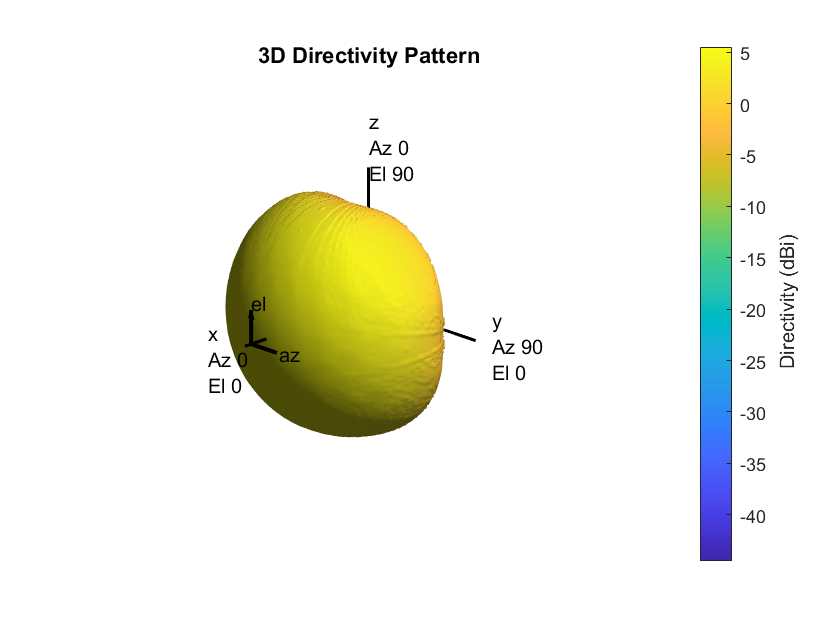

load dipolerefarray
elemfieldpatternfinite = sqrt(FiniteArrayPatData.ElemPat);
arraypatternfinite = FiniteArrayPatData.ArrayPat;
bandwidth = 3.75e6;
customAntFinite = buildCustomAntenna(elemfieldpatternfinite,plotFrequency,bandwidth,az,el);
figure
pattern(customAntFinite,plotFrequency)

**Create Uniform Rectangular** **Array** **with embedded element pattern**

As done before, create a uniform rectangular array with the custom antenna element.

myURA2 = phased.URA;
myURA2.Element = customAntFinite;
myURA2.Size = [Nrow Ncol];
myURA2.ElementSpacing = [drow dcol];

**E and H plane slice -** **array** **With embedded element pattern**

Calculate the pattern slices in two orthogonal planes - E and H for the array with the embedded element pattern and the embedded element pattern itself. In addition, since the full wave data for the array pattern is also available use this to compare results.

Darray2_E = pattern(myURA2,plotFrequency,0,elang_plot);
Darray2_Enormlz = Darray2_E - max(Darray2_E);
% H-plane
Darray2_H = pattern(myURA2,plotFrequency,azang_plot,0);
Darray2_Hnormlz = Darray2_H - max(Darray2_H);

**E and H plane slice -** **array** **With embedded element pattern**

Calculate the pattern slices in two orthogonal planes - E and H for the array with the embedded element pattern and the embedded element pattern itself. In addition, since the full wave data for the array pattern is also available use this to compare results.


plotFrequency=75e6; Termination = 50;
Darray2_E = pattern(arrayObject,plotFrequency,0,elang_plot);
Darray2_Enormlz = Darray2_E - max(Darray2_E);
% H-plane
Darray2_H = pattern(arrayObject,plotFrequency,azang_plot,0);
Darray2_Hnormlz = Darray2_H - max(Darray2_H);

**E and H plane slice - embedded element pattern from finite array**

DSEP2_E = pattern(customAntFinite,plotFrequency,0,elang_plot);
DSEP2_Enormlz = DSEP2_E - max(DSEP2_E);
DSEP2_H = pattern(customAntFinite,plotFrequency,azang_plot,0);
DSEP2_Hnormlz = DSEP2_H - max(DSEP2_H);

%E and H plane slice - full wave analysis of finite array

azang_plot1 = -90:2:90;
elang_plot1 = -90:2:90;

Darray3_E = FiniteArrayPatData.EPlane;
Darray3_Enormlz = Darray3_E - max(Darray3_E);

Darray3_H = FiniteArrayPatData.HPlane;
Darray3_Hnormlz = Darray3_H - max(Darray3_H);

**Comparison of** **array** **patterns**

The array patterns in the two orthogonal planes are plotted here.

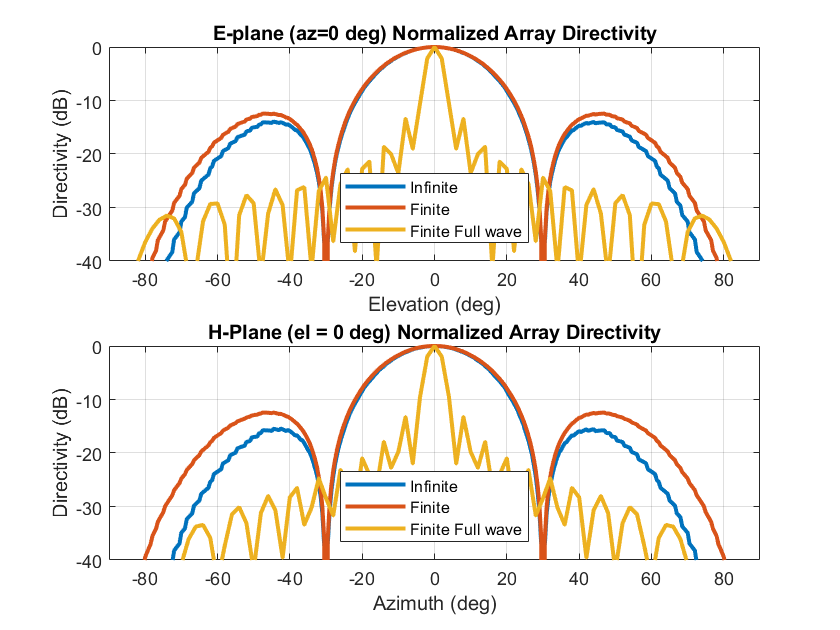

figure
subplot(211)
plot(elang_plot,Darray1_Enormlz,elang_plot,Darray2_Enormlz,elang_plot1,Darray3_Enormlz,'LineWidth',2)
grid on
axis([min(elang_plot) max(elang_plot) -40 0]);
legend('Infinite','Finite','Finite Full wave','location','best')
xlabel('Elevation (deg)')
ylabel('Directivity (dB)')
title('E-plane (az=0 deg) Normalized Array Directivity')
subplot(212)
plot(azang_plot,Darray1_Hnormlz,azang_plot,Darray2_Hnormlz,azang_plot1,Darray3_Hnormlz,'LineWidth',2)
grid on
axis([min(azang_plot) max(azang_plot) -40 0]);
legend('Infinite','Finite','Finite Full wave','location','best')
xlabel('Azimuth (deg)')
ylabel('Directivity (dB)')
title('H-Plane (el = 0 deg) Normalized Array Directivity')

The pattern plots in the two planes reveals that all three analysis approaches suggest similar behavior out to +/-40 degree from boresight. Beyond this range, it appears that using the scan element pattern for all elements in a URA (i.e. pattern multiplication principle) underestimates the sidelobe level compared to the full wave analysis of a finite array. The one possible reason for this could be the edge effect from the finite size array.

**Comparison of element patterns**

The element patterns from the infinite array analysis and the finite array analysis are compared here.

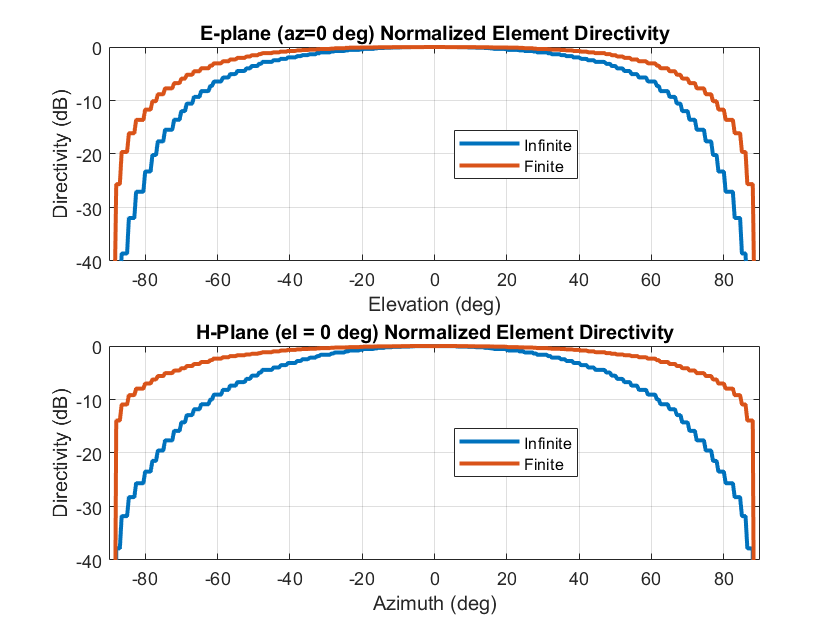

figure
subplot(211)
plot(elang_plot,DSEP1_Enormlz,elang_plot,DSEP2_Enormlz,'LineWidth',2)
grid on
axis([min(azang_plot) max(azang_plot) -40 0]);
legend('Infinite','Finite','location','best')
xlabel('Elevation (deg)')
ylabel('Directivity (dB)')
title('E-plane (az=0 deg) Normalized Element Directivity')
subplot(212)
plot(azang_plot,DSEP1_Hnormlz,azang_plot,DSEP2_Hnormlz,'LineWidth',2)
grid on
axis([min(azang_plot) max(azang_plot) -40 0]);
legend('Infinite','Finite','location','best')
xlabel('Azimuth (deg)')
ylabel('Directivity (dB)')
title('H-Plane (el = 0 deg) Normalized Element Directivity')

The pattern plots suggests that the behavior out to +/-40 degree from boresight is approximately the same. Outside of this range there is greater drop off in the H-plane pattern from the infinite array analysis as compared to the finite array.**Scan Behavior with** **Infinite** **Array** **Scan Element Pattern**

Scan the array based on the infinite array scan element pattern in the elevation plane defined by azimuth = 0 deg and plot the normalized directivity. Also, overlay the normalized scan element pattern.

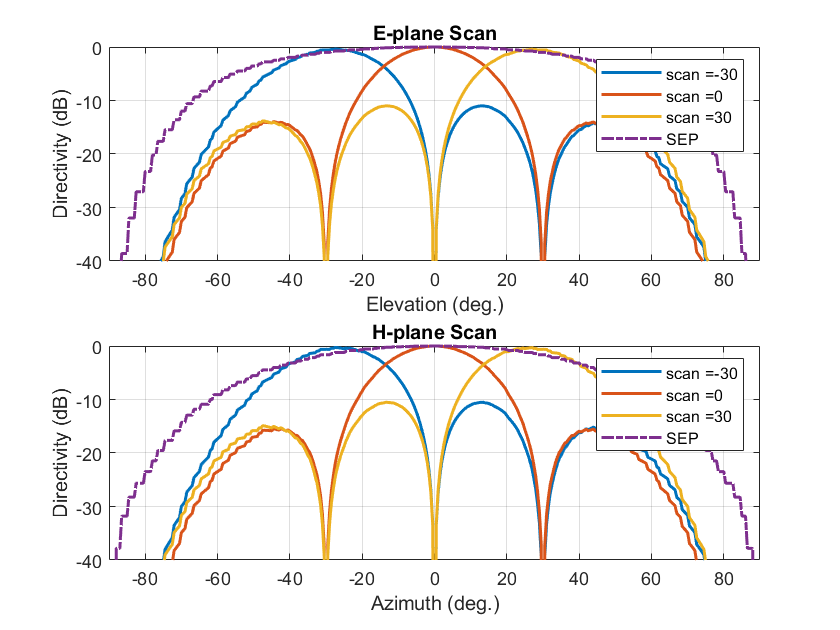

scanURA(myURA1,plotFrequency,azang_plot,elang_plot,DSEP1_Enormlz,DSEP1_Hnormlz);

Note the overall shape of the normalized array pattern approximately follows the normalized scan element pattern. This is also predicted by the pattern multiplication principle.

**Conclusion**

Infinite array analysis is one of the tools deployed to analyze and design large finite arrays. The analysis assumes that all elements are identical, have uniform excitation amplitude and that edge effects can be ignored. The isolated element pattern is replaced with the scan element pattern which includes the effect of mutual coupling.

**References**

A part of this work has been studied and implemented based on the following documentation:

https://in.mathworks.com/help/antenna/ug/modeling-mutual-coupling-in-large-arrays-using-infinite-array-analysis.html?searchHighlight=infinite%20array&s_tid=srchtitle